# 1 Simple  filters

## 1.1    Impulse responses, transfer functions

% running sum generation first one of order 3 and second one with order 5 

% orders of the moving sums 
N1 = 3 ;
N2 = 5 ; 

hRS_1 = moving_sum(N1,1) ; 
hRS_2 = moving_sum(N2,1) ; 


% here are the polynomial coefs 

num1= [1,1,1,1];
den1 = [1,0,0,0];
HRS_1 = tf(num1,den1)

HRS_1 =
 
  s^3 + s^2 + s + 1
  -----------------
         s^3
 
Continuous-time transfer function.




num2= [1,1,1,1,1,1];
den2 = [1,0,0,0,0,0];
HRS_2 = tf(num2,den2)

HRS_2 =
 
  s^5 + s^4 + s^3 + s^2 + s + 1
  -----------------------------
               s^5
 
Continuous-time transfer function.



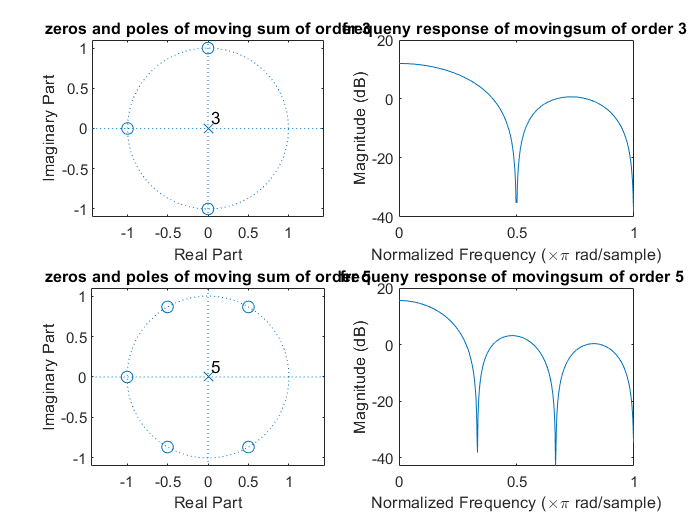


% Finding the roots of the z transforms of the running sums 

% zeros of HRS1
zeros1 =roots(num1) ;
%poles of HRS1 
poles1  = roots(den1);

% zeros of HRS2
zeros2 = roots(num2) ;
% poles of HRS2
poles2 = roots(den2) ;

% ploting roots and poles of the z transforms on zplane 

%  zplane is a matlab fnc that
% finds the zeros and poles of the transfer function 
% represented by the digital filter, d. 
% The pole-zero plot is displayed in FVTool.



% [h,w] = freqz(d,n)  : returns the n-point complex 
% frequency response for the digital filter d.

[h1,w1] = freqz(num1,den1) ; 
[h2,w2] = freqz(num2,den2) ;

figure()
subplot(2,2,1)
% plots the zeros and poles of HRS1
zplane(num1,den1) ;
title("zeros and poles of moving sum of order 3")
subplot(2,2,3)
% plots the zeros and poles of HRS2
zplane(num2, den2) ;
title("zeros and poles of moving sum of order 5")
subplot(2,2,2)
% ploting the frequency response 
plot(w1/pi,20*log10(abs(h1)))
title('frequeny response of movingsum of order 3 ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')
subplot(2,2,4)
% ploting the frequency response 
plot(w2/pi,20*log10(abs(h2)))
title('frequeny response of movingsum of order 5  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')



% generation of moving average of order 3 and order 5 to compare theirfrequency
% response to the moving sum of the same order 

num3 = num1 ;
den3 = (N1 + 1) * den1 ;
HMA_1 = HRS_1 / (N1 + 1 ) ;
[H1,W1] = freqz(num3,den3) ; 

num4 = num2 ;
den4 = (N2 + 1) * den2 ;
HMA_2 = HRS_2 / (N2 + 1 ) ;
[H2,W2] = freqz(num4,den4) ;

figure()

subplot(2,2,1)
% ploting the frequency response of the moving sum of order 3
plot(w1/pi,20*log10(abs(h1)))
title('frequeny response of moving sum of order 3 ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(2,2,2)
% ploting the frequency response of the moving average of order 3

plot(W1/pi,20*log10(abs(H1)))
title('frequeny response of moving average of order 3  ')
ylim = ([-100 20])

ylim =   -100    20


xlim([0 1])
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(2,2,3)
% ploting the frequency response of the moving sum of order 5
plot(w2/pi,20*log10(abs(h2)))
title('frequeny response of moving sum of order 5  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(2,2,4)
% ploting the frequency response of the moving average of order 5
plot(W2/pi,20*log10(abs(H2)))
title('frequeny response of moving average of order 5 ')
ylim = ([-100 20])

ylim =   -100    20


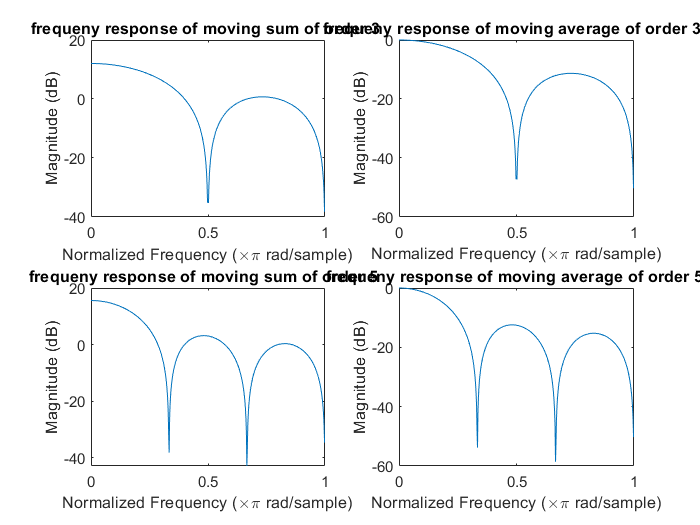

xlim([0 1])
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

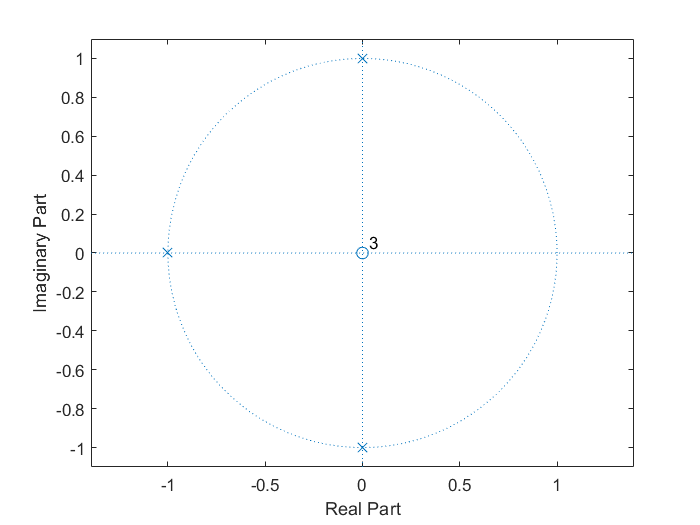

 

% zplane(b,a), where b and a are row vectors, 
% first uses roots to find the zeros and poles of the transfer function 
% represented by the numerator coefficients b and the denominator coefficients a.
num1_= [1] ;
den1_ = [1,1,1,1] ;
figure()
zplane(num1_,den1_)

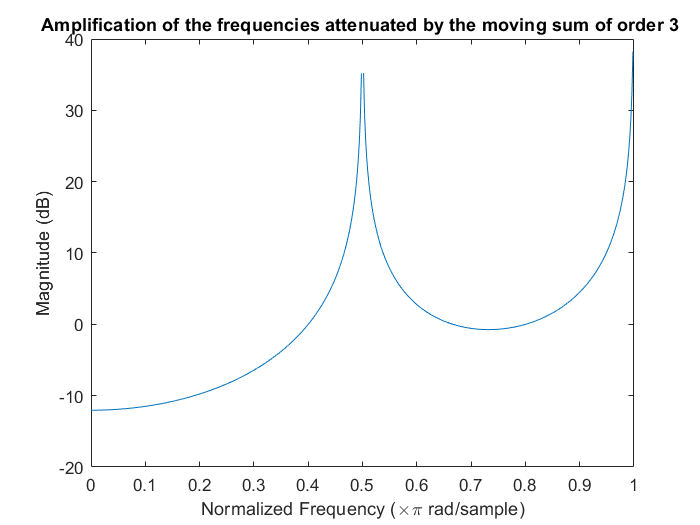


% [h,w] = freqz(b,a,n) : returns the n-point frequency response vector h 
% and the corresponding angular frequency vector w for the digital filter 
% with transfer function coefficients stored in b and a
[h_,w_] = freqz(num1_,den1_);
figure()
plot(w_/pi,20*log10(abs(h_)))
title(' Amplification of the frequencies attenuated by the moving sum of order 3  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

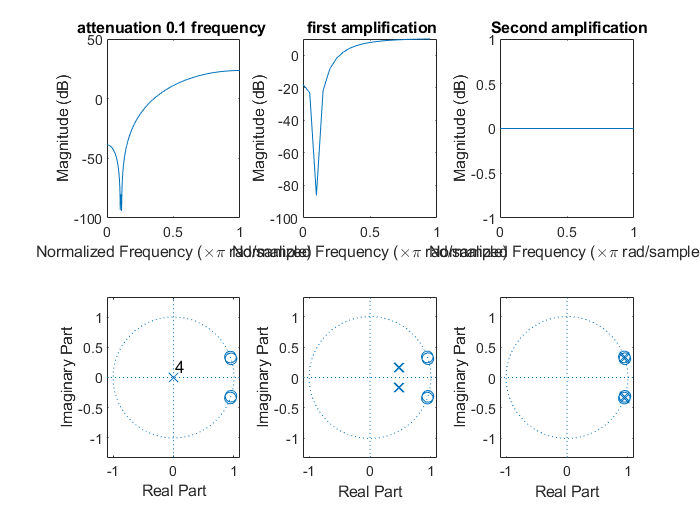

 

% if we want to attenuate the normalized freqeuncy 0.1 pi by putting 4
% zeros ( 2 paires of complex conjugates ) 
% H(z) =( z - e ^-0.1 pi )( z - e^0.1 pi )( z - e ^-0.11 pi )( z - e^0.11 pi )
figure()
subplot(2,3,4)
b_= [1,-3.78387,5.57932,-3.78387,1] ;
a_ = [1] ;
zplane(b_ ,a_)

% [h,w] = freqz(b,a,n) : returns the n-point frequency response vector h 
% and the corresponding angular frequency vector w for the digital filter 
% with transfer function coefficients stored in b and a
[h3,w3] = freqz(b_,a_);
subplot(2,3,1)
plot(w3/pi,20*log10(abs(h3)))
title(' attenuation 0.1 frequency  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

% How does the frequency response change whenyou increase R and
% when R approaches 1? 

% As R approches 1 , the poles approches the zeros and also the 0.1
% normalized frequency , reducing the effect of the attenuation caused by
% the zeros nearby , thus this contributes to amplify back the 0.1
% normalized frequency

% H(z) =(z-e ^-0.1 pi)(z-e^0.1 pi )(z-e ^-0.11 pi)(z-e^0.11) / (z-0.5e^-0.1 pi)(z-0.5e^0.1 pi )(z-0.5e ^-0.11 pi)(z-0.5e^0.11pi ) )
B_= [1,-3.78387,5.57932,-3.78387,1] ;
A_ = [1,-1.89184,1.39483,-0.472984,0.0625] ;

subplot(2,3,5)
zplane(B_ ,A_)

[h4,w4] = freqz(B_,A_,20);
subplot(2,3,2)
plot(w4/pi,20*log10(abs(h4)))
title(' first amplification')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')


B= [1,-3.78387,5.57932,-3.78387,1] ;
A=[1,-3.78387,5.57932,-3.78387,1] ;
subplot(2,3,6)
zplane(B ,A)
[h5,w5] = freqz(B,A);
subplot(2,3,3)
plot(w5/pi,20*log10(abs(h5)))
title(' Second amplification')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

## 1.2    The power of poles and zeros

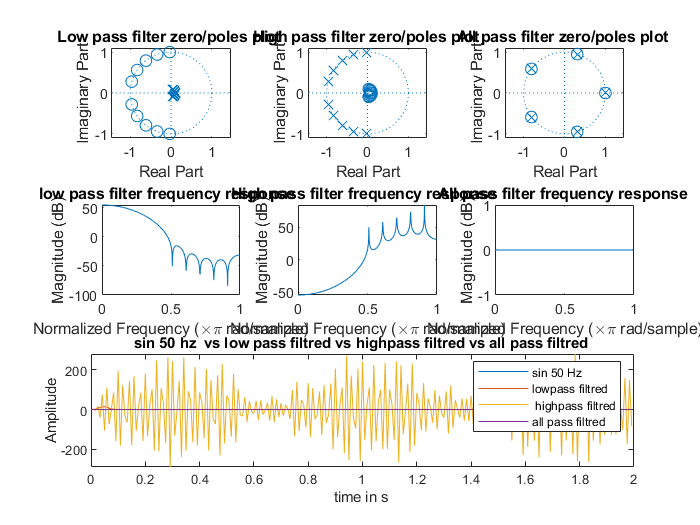

% we need to use zeros and poles to design low pass filter ( attenuate
% high frequencies )
clear
% let's consider the high frequency as  |f| >  pi/2 so we need to add poles
% along the right part of the unit circle and zeros along it's left side 


% matlab function to find the polynomial coefs from the zeros

x1 =0.01:0.1:0.49 ; % first quarter of unit cercle 
x2 =0.51:0.1:0.99 ;  % second quarter of unit cercle 
x3 =-x2 ;   % third quarter of unit cercle 
x4 =-x1 ; % fourth quarter of unit cercle


% High frequencies 
xH = [x2 , x3] ;
% Low ferquencies 
xL = [x1 , x4] ;

% poles 
den_roots= transpose (0.1*exp(1i*(pi)*xL) ) ;
% zeros
num_roots = transpose (exp(1i*(pi)*xH) ) ;
% to find the numerator and denominator coefs 
num = poly(num_roots) ; 
den = poly(den_roots) ;
[h,w] = freqz(num,den);
figure()
subplot(3,3,4)
plot(w/pi,20*log10(abs(h)))
title('low pass filter frequency response  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')
subplot(3,3,1)
zplane(num_roots ,den_roots)
title('Low pass filter zero/poles plot ')

% Now if we want to design a high pass filter we can take the reciprocial
% of the low pass filiter response function such as the denominateur of the
% low pass filter is the numerator of the high pass filter and vis versa

% poles 
den_roots2 = transpose (exp(1i*(pi)*xH) ) ;
% zeros
num_roots2 = transpose (0.1*exp(1i*(pi)*xL) ) ;
num_ = poly(num_roots2) ; 
den_= poly(den_roots2) ;

[h_,w_] = freqz(num_,den_);
subplot(3,3,5)
plot(w_/pi,20*log10(abs(h_)))
title('High pass filter frequency response  ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(3,3,2)
zplane(num_roots2,den_roots2)
title('High pass filter zero/poles plot ')

% To design an all pass filter ( that let all frequencies pass ) we need to
% compensate the attenuation of a frequency caused by a zero nearby with
% the unit cercle by an amplification adding a poles in the same position
% this will result in a frequency response having the same numerator and
% denominator

p =0.4:0.4:2 ;

%poles 
denroots = transpose(exp(1i*(pi)*p) );
% zeros
numroots = denroots  ;
numerator = poly(numroots) ; 
denominator = poly(denroots) ;

[H,W] = freqz(numerator,denominator);
subplot(3,3,6)
plot(W/pi,20*log10(abs(H)))
title('All pass filter frequency response ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(3,3,3)
zplane(numroots ,denroots)
title('All pass filter zero/poles plot ')

fs = 120 ; % sampling frequency in Hz
T_sin = 2 ; % time duration in seconds 
t_sin = 0:1/fs:T_sin-(1/fs); % time vector with sampling freq = 120 Hz
sin_50= sin(2*pi*50*t_sin); % sin function with 50 HZ fundamental frequency



% we know that the unit cercle covers the frequencies from 0 to fs/ 2= 60
% Hz ,than the fundamental freqeucny of the sin is within the high
% frequencies range ( bigger than 30 Hz ) , so we expect that it will be attenuated by the lowpass filter 
% we expected to be amplitfied by the high pass filter and unchanged 

%low pass filtrer 50Hz sin signal
lowpass_sin = filter(num,den,sin_50) ; 
%High pass filter 50 Hz sin signal
highpass_filter = filter(num_,den_,sin_50) ; 
% All pass filter 50 hz sin signal
allpass_filter = filter(numerator,denominator,sin_50) ; 

subplot(3,3,[7 8 9])

plot(t_sin , sin_50)
hold on 
plot(t_sin,lowpass_sin)
plot(t_sin,highpass_filter)
plot(t_sin,allpass_filter)
title(' sin 50 hz  vs low pass filtred vs highpass filtred vs all pass filtred  ' )
xlabel('time in s ')
ylabel('Amplitude')
legend('sin 50 Hz' , 'lowpass filtred ' , ' highpass filtred ' , 'all pass filtred ')
xlim([0 2])



%sound(sin_50)

%sound(lowpass_sin)

%sound(highpass_filter)

sound(allpass_filter)

% How do the suppressed frequencies depend on the chosen sampling frequency of the input signal?

% the sampling frequency gives definies the high and low freqeuncy ranges
% Suppose we have a sampling freqeuncy of fs , than the upper half of the
% unit cercle in z domain will range from 0 to [fs/2 , 0 to fs/4] will be the
% low frequency range and [fs/4 f/2] is the high frequency range . Thus we
% can conclude that yes the sampling frequency influence the suppresed
% frequencies .


%How does  the  processing  of  the  sound  change  when  you  use  more/less  poles/zeros?   Can  you already estimate the transfer function by looking at the pole-zero plot?  Can you say anythingabout the expected gain and phase shift of single responses

% By adding sevreal zeros we can attenuate a larger frequency range which
% is not possible with only one zero we can only attenuate one particular
% frequency , same thing applies for the poles , the use of several poles
% enables the amplification of larger frequency range . 


% Yes we can guess how the transfer function looks like using to the zero/poles plot . 
% the position of the poles will defines what are the frequencies that will
% be amplified/attenuates and how (if the pole/zero is within the unit cercle 
% than the amplification/attenuation tend to infinite if the pole/zero is inside
% then the amplification/attenuation is finite
% So poles allows use to generate the denominator of the frequency response
% and the zeros allows use to generate the nominator of the frequency response

% the gain of a given frequency is given by the quotient of product of the distancesto
% the zeros and the product of the distances to the poles 
% ( Magnitude (w ) = π |w - zi| /  π |w - pi| where zi are the zeros and pi
% the poles of the transfer function , the phase is given by the sum of
% angles to the zeros minus the angles to the poles 



